# Projeto Prático EPOT 2: Conversor Buck Quadrático – Modelo 2

O conversor CC-CC Buck Quadrático (Modelo 2) apresenta o circuito de potência ilustrado na Figura a seguir.

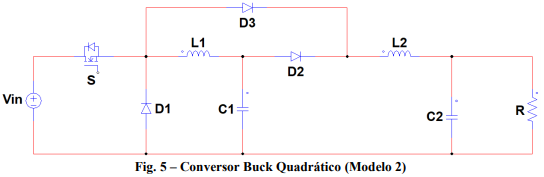

**OBS.:** Uma vez que para os conversores CC-CC quadráticos deste projeto existem dois tipos de representação no espaço de estados, uma para chave fechada e outra para chave aberta, os cálculos de M e N dependerão das matrizes de sistema e de entrada utilizadas. O que vai definir a utilização das matrizes de sistema e de entrada para chave aberta ou para chave fechada dos conversores será o resultado da comparação entre o sinal equivalente à razão cíclica D e a onda dente-de-serra vds, conforme ilustrado na Fig. 7. Logo, se D for maior que vds, utiliza-se as matrizes de sistema e de entrada para a condição de chave fechada, e se D for menor que vds, utiliza-se as matrizes de sistema e de entrada para a condição de chave aberta na solução do modelo matemático.

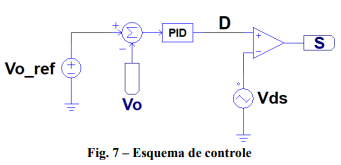

## Objetivos do Projeto

- Desenvolver os equacionamentos necessários para o projeto das indutâncias e capacitâncias do circuito;

- Definir as especificações de projeto do conversor; 

- Realizar a modelagem no conversor no espaço de estados; 

- Implementar um algoritmo para solução numérica das variáveis de estado do circuito do conversor, tomando por base a integração trapezoidal. O passo de integração adotado para a solução deverá ser 10 vezes menor que o período de chaveamento escolhida para o conversor.

**Operação do conversor em malha aberta**

- Demonstrar as formas de onda das correntes nos indutores e das tensões nos capacitores para uma razão cíclica de operação estabelecida;

- Demonstrar a forma de onda da tensão de saída a um degrau de razão cíclica;

- Estimar uma função de transferência aproximada de segunda ordem para o sistema; 

- Projetar o controlador PID da malha de controle de tensão.

**Operação do conversor em malha fechada**

- Implementar a malha de controle com o controlador PID projetado; 

- Demonstrar as formas de onda das correntes nos indutores e das tensões nos capacitores para uma dada referência de tensão estabelecida; 

- Demonstrar o comportamento da tensão de saída do conversor a um degrau de referência de tensão, a uma variação de carga e a um afundamento na tensão de alimentação. 

## 1 Dimensionamento das indutores e capacitores

clear
clc
syms Vo Vin D L1 L2 C1 C2 fch Delta_il1 Delta_il2 Delta_vc1 Delta_vc2 R Il1_med Il2_med D_med
% determinando equação para D e encontrando as raízes
eqD = simplify(-D^2+2*D-(Vo/Vin));

### 1.1 Razão cíclica D

razaoCiclicaD = solve(eqD,D)

$$razaoCiclicaD = \left(\begin{array}{c} \sqrt{\frac{\mathrm{Vin}-\mathrm{Vo}}{\mathrm{Vin}}}+1\\ 1-\sqrt{\frac{\mathrm{Vin}-\mathrm{Vo}}{\mathrm{Vin}}} \end{array}\right)$$

### 1.2 Indutâncias L1 e L2

valorL1 = simplify(Vin*(D^2 - D)/(Delta_il1*fch))

$$valorL1 = \frac{\text{D}\,\mathrm{Vin}\,\left(\text{D}-1\right)}{\Delta_{\mathrm{il1}}\,\mathrm{fch}}$$

valorL2 = simplify((Vin-Vo)*D/(Delta_il2*fch));
valorL2 = simplify(subs(valorL2,Vo,(2*D -D^2)*Vin))

$$valorL2 = \frac{\text{D}\,\mathrm{Vin}\,{\left(\text{D}-1\right)}^{2}}{\Delta_{\mathrm{il2}}\,\mathrm{fch}}$$

### 1.3 Correntes médias nos indutores L1 e L2

Il1_med = simplify((Vo^2/(R*Vin*D))-(Vo/R))

$$Il1\_med = \frac{\mathrm{Vo}\,\left(\mathrm{Vo}-\text{D}\,\mathrm{Vin}\right)}{\text{D}\,R\,\mathrm{Vin}}$$

Il1_med = simplify(subs(Il1_med,Vo,(2*D -D^2)*Vin))

$$Il1\_med = \frac{\text{D}\,\mathrm{Vin}\,\left({\text{D}}^{2}-3\,\text{D}+2\right)}{R}$$

Il2_med = Vo/R

$$Il2\_med = \frac{\mathrm{Vo}}{R}$$

### 1.4 Capacitâncias C1 e C2

valorC1 = simplify(Il1_med*D/(Delta_vc1*fch))

$$valorC1 = \frac{{\text{D}}^{2}\,\mathrm{Vin}\,\left({\text{D}}^{2}-3\,\text{D}+2\right)}{\Delta_{\mathrm{vc1}}\,R\,\mathrm{fch}}$$

valorC1 = simplify(subs(valorC1,Vo,(2*D -D^2)*Vin))

$$valorC1 = \frac{{\text{D}}^{2}\,\mathrm{Vin}\,\left({\text{D}}^{2}-3\,\text{D}+2\right)}{\Delta_{\mathrm{vc1}}\,R\,\mathrm{fch}}$$

valorC2 = ((Vin-Vo)*D/(8*L2*Delta_vc2*fch^2))

$$valorC2 = \frac{\text{D}\,\left(\mathrm{Vin}-\mathrm{Vo}\right)}{8\,\Delta_{\mathrm{vc2}}\,L_{2}\,{\mathrm{fch}}^{2}}$$

valorC2 = simplify(subs(valorC2,Vo,(2*D -D^2)*Vin))

$$valorC2 = \frac{\text{D}\,\mathrm{Vin}\,{\left(\text{D}-1\right)}^{2}}{8\,\Delta_{\mathrm{vc2}}\,L_{2}\,{\mathrm{fch}}^{2}}$$

### 1.5 Tensão média nos capacitores

VC1_med = Vin*D

$$VC1\_med = \text{D}\,\mathrm{Vin}$$

VC2_med = Vo

$$VC2\_med = \mathrm{Vo}$$

## 2 Especificações do projeto do conversor

### 2.1 Definições de projeto

%%
Po = 100;
Vin = 30;
Vo = 20;
fch = 10e3;
R = Vo^2/Po;
valorR = R

valorR = 4

D = double(subs(razaoCiclicaD(2)))

D = 0.4226

double(subs(Il1_med))*0.2

ans = 0.5774

Delta_il1 = double(abs(0.2*subs(Il1_med)));
Delta_il2 = abs(0.2*subs(Il2_med));
Delta_vc1 = 0.01*double(subs(VC1_med));
Delta_vc2 = 0.01*double(subs(VC2_med));
valorL1 = abs(double(subs(valorL1)));
num2eng(valorL1)

ans = '1.2679e-3'

valorL2 = double(subs(valorL2));
num2eng(valorL2)

ans = '422.65e-6'

valorC1 = abs(double(subs(valorC1)));
num2eng(valorC1)

ans = '962.25e-6'

valorC2 = double(subs(subs(valorC2),L2,valorL2));
num2eng(valorC2)

ans = '62.5e-6'

## 3 Modelagem em espaço de estados

### 3.1 Representação do sistema em espaço de estados


$$\overset{\bullet }{x\left(t\right)} =A\cdot x\left(t\right)+B\cdot u\left(t\right)$$



$$y\left(t\right)=\;C\cdot x\left(t\right)+\;E\cdot u\left(t\right)$$


onde 

$x\left(t\right)=\left\lbrack \begin{array}{c}
il_1 \left(t\right)\\
il_2 \left(t\right)\\
vc_1 \left(t\right)\\
vc_2 \left(t\right)
\end{array}\right\rbrack$ , $u\left(t\right)=\left\lbrack V_{\mathrm{in}} \left(t\right)\right\rbrack$e $y\left(t\right)=\left\lbrack \begin{array}{c}
\mathit{Vo}\left(t\right)
\end{array}\right\rbrack$

U = [Vin];
syms R

### 3.2 Chave fechada

A1_symb = [0 0 (-1/L1) 0;0 0 0 (-1/L2);(1/C1) 0 0 0;0 (1/C2) 0 (-1/(R*C2))]

$$A1\_symb = \left(\begin{array}{cccc} 0 & 0 & -\frac{1}{L_{1}} & 0\\ 0 & 0 & 0 & -\frac{1}{L_{2}}\\ \frac{1}{C_{1}} & 0 & 0 & 0\\ 0 & \frac{1}{C_{2}} & 0 & -\frac{1}{C_{2}\,R} \end{array}\right)$$

B1_symb = [(1/L1);(1/L2);0;0]

$$B1\_symb = \left(\begin{array}{c} \frac{1}{L_{1}}\\ \frac{1}{L_{2}}\\ 0\\ 0 \end{array}\right)$$

c1 = [0 0 0 1];
E1 = [0];

### 3.3 Chave aberta

A2_symb = [0 0 (-1/L1) 0;0 0 (1/L2) (-1/L2);(1/C1) (-1/C1) 0 0;0 (1/C2) 0 (-1/(R*C2))]

$$A2\_symb = \left(\begin{array}{cccc} 0 & 0 & -\frac{1}{L_{1}} & 0\\ 0 & 0 & \frac{1}{L_{2}} & -\frac{1}{L_{2}}\\ \frac{1}{C_{1}} & -\frac{1}{C_{1}} & 0 & 0\\ 0 & \frac{1}{C_{2}} & 0 & -\frac{1}{C_{2}\,R} \end{array}\right)$$

B2_symb = zeros(4,1)

B2_symb =      0
     0
     0
     0


c2 = [0 0 0 1]

c2 =      0     0     0     1


E2 = [0]

E2 = 0

## 4 Solução numérica das variáveis de estado

D = double(subs(razaoCiclicaD(2)))

D = 0.4226

D_med = D;
L1 = abs(double(subs(valorL1)));
L2 = abs(double(subs(valorL2)));
C1 = abs(double(subs(valorC1)));
C2 = abs(double(subs(valorC2)));
R  = abs(double(subs(valorR)));
A1 = double(subs(A1_symb))

A1 = 	1.0e+04 *

         0         0   -0.0789         0
         0         0         0   -0.2366
    0.1039         0         0         0
         0    1.6000         0   -0.4000


A2 = double(subs(A2_symb))

A2 = 	1.0e+04 *

         0         0   -0.0789         0
         0         0    0.2366   -0.2366
    0.1039   -0.1039         0         0
         0    1.6000         0   -0.4000


B1 = double(subs(B1_symb))

B1 = 	1.0e+03 *

    0.7887
    2.3660
         0
         0


B2 = double(subs(B2_symb))

B2 =      0
     0
     0
     0



tempo_f = 0.15;
Delta_t = double((1/fch)/100);
t = 0:Delta_t:tempo_f;
DenteSerra = (sawtooth(2*pi*fch*t)*0.5)+0.5;
t_size = size(t);
t_size = t_size(1,2);
x = zeros(t_size,rank(A1));
u = ones(t_size,1)*Vin;
M1 = inv(eye(rank(A1))-((Delta_t/2)*A1))*(eye(rank(A1))+(Delta_t/2)*A1);
N1 = inv(eye(rank(A1))-((Delta_t/2)*A1))*((Delta_t/2)*B1);
M2 = inv(eye(rank(A2))-((Delta_t/2)*A2))*(eye(rank(A2))+(Delta_t/2)*A2);
N2 = inv(eye(rank(A2))-((Delta_t/2)*A2))*((Delta_t/2)*B2);
for i = 1:t_size
    if D < DenteSerra(i)
        M = M2;
        N = N2;
    else
        M = M1;
        N = N1;
    end
    if i == 1
        x(1,:) = zeros(1,4);
    else
        x(i,:) =(M*x(i-1,:)'+N*(u(i)+u(i-1)))';
    end
    if x(i,1) < 0
        x(i,1) = 0;
    end
    if x(i,2) < 0
        x(i,2) = 0;
    end
end

IL1 = x(:,1);
IL2 = x(:,2);
VC1 = x(:,3);
VC2 = x(:,4);
VC2_ma = VC2;

### **4.1 Operação do conversor em malha aberta**

#### 4.1.1 Formas de onda das correntes nos indutores para uma razão cíclica D

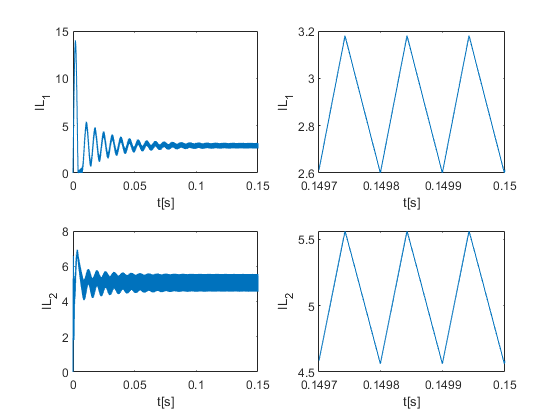

ti = t_size-300;
tempo_f = ti+300;

figure(1);
subplot(2,2,1)
plot(t,IL1);
xlabel('t[s]');
ylabel('IL_1');
subplot(2,2,2)
plot(t(ti:tempo_f),IL1(ti:tempo_f));
xlabel('t[s]');
ylabel('IL_1');
subplot(2,2,3)
plot(t,IL2);
xlabel('t[s]');
ylabel('IL_2');
subplot(2,2,4)
plot(t(ti:tempo_f),IL2(ti:tempo_f));
xlabel('t[s]');
ylabel('IL_2');

Delta_il1_projetado = double(Delta_il1)

Delta_il1_projetado = 0.5774

Delta_il1_calculado = max(IL1(ti:tempo_f))-min(IL1(ti:tempo_f))

Delta_il1_calculado = 0.5804

Delta_il2_projetado = double(Delta_il2)

Delta_il2_projetado = 1

Delta_il2_calculado = max(IL2(ti:tempo_f))-min(IL2(ti:tempo_f))

Delta_il2_calculado = 0.9997

#### 4.1.2 Formas de onda das tensões nos capacitores para uma razão cíclica D

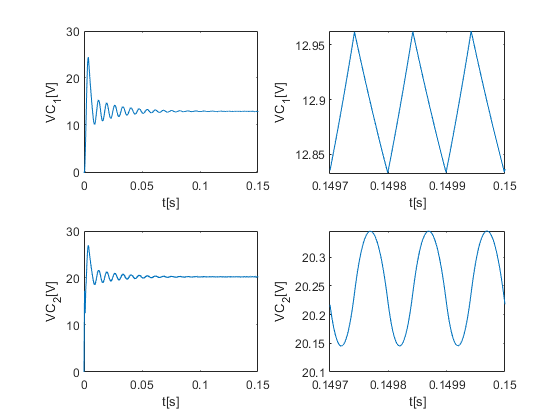

figure(2);
subplot(2,2,1)
plot(t,VC1);
xlabel('t[s]');
ylabel('VC_1[V]');
subplot(2,2,2)
plot(t(ti:tempo_f),VC1(ti:tempo_f));
xlabel('t[s]');
ylabel('VC_1[V]');
subplot(2,2,3)
plot(t,VC2);
xlabel('t[s]');
ylabel('VC_2[V]');
subplot(2,2,4)
plot(t(ti:tempo_f),VC2(ti:tempo_f));
xlabel('t[s]');
ylabel('VC_2[V]');

Delta_vc1_projetado = double(Delta_vc1)

Delta_vc1_projetado = 0.1268

Delta_vc1_calculado = max(VC1(ti:tempo_f))-min(VC1(ti:tempo_f))

Delta_vc1_calculado = 0.1296

Delta_vc2_projetado = double(Delta_vc2)

Delta_vc2_projetado = 0.2000

Delta_vc2_calculado = max(VC2(ti:tempo_f))-min(VC2(ti:tempo_f))

Delta_vc2_calculado = 0.2005

#### 4.1.3 Forma de onda da tensão de saída a um degrau de razão cíclica

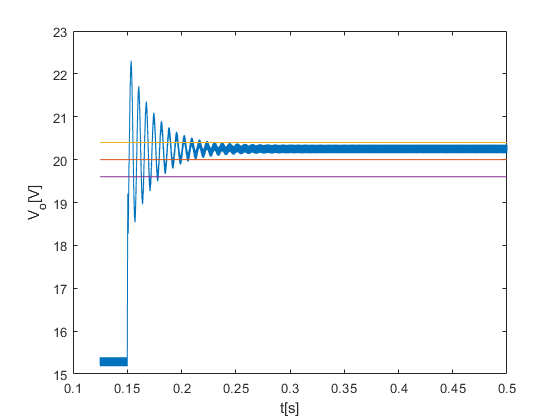

tempo_f = 0.5;
Delta_t = double((1/fch)/100);
t = 0:Delta_t:tempo_f;
DenteSerra = (sawtooth(2*pi*fch*t)*0.5)+0.5;
t_size = size(t);
t_size = t_size(1,2);
x = zeros(t_size,rank(A1));
u = ones(t_size,1)*Vin;
M1 = inv(eye(rank(A1))-((Delta_t/2)*A1))*(eye(rank(A1))+(Delta_t/2)*A1);
N1 = inv(eye(rank(A1))-((Delta_t/2)*A1))*((Delta_t/2)*B1);
M2 = inv(eye(rank(A2))-((Delta_t/2)*A2))*(eye(rank(A2))+(Delta_t/2)*A2);
N2 = inv(eye(rank(A2))-((Delta_t/2)*A2))*((Delta_t/2)*B2);
for i = 1:t_size
    if t(i) < 0.15
        D = 0.2929;
    else 
        D = 0.4226;
    end
    if D < DenteSerra(i)
        M = M2;
        N = N2;
    else
        M = M1;
        N = N1;
    end
    if i == 1
        x(1,:) = zeros(1,4);
    else
        x(i,:) =(M*x(i-1,:)'+N*(u(i)+u(i-1)))';
    end
    if x(i,1) < 0
        x(i,1) = 0;
    end
    if x(i,2) < 0
        x(i,2) = 0;
    end
end

IL1 = x(:,1);
IL2 = x(:,2);
VC1 = x(:,3);
VC2 = x(:,4);
figure(3);
ti = floor(t_size/4)-1;
regime_permanente = 20*ones(t_size,1);
plot(t(ti:t_size),VC2(ti:t_size),t(ti:t_size),regime_permanente(ti:t_size),t(ti:t_size),regime_permanente(ti:t_size)*1.02,t(ti:t_size),regime_permanente(ti:t_size)*0.98);
xlabel('t[s]');
ylabel('V_o[V]');

#### 4.1.4 Função de transferência aproximada de segunda ordem para o sistema

Parâmetros

Vmax=22.29;
Vinicial=15;
Vfinal=20;
Dinicial=0.2929;
Dfinal=0.4226;
Tinicial=0.15;
Ts=0.2183-Tinicial

Ts = 0.0683

Cálculos

K=(Vfinal-Vinicial)/(Dfinal-Dinicial)

K = 38.5505

Up=((Vmax-Vfinal)/Vfinal)*100

Up = 11.4500

z=double((-log(Up/100))/(sqrt((pi^2)+(log(Up/100))^2)))

z = 0.5678

Wn=double(4/(z*Ts))

Wn = 103.1379

s = tf('s');
Gs=(K*(Wn^2))/(s^2+2*z*Wn*s+Wn^2)


Gs =
 
          4.101e05
  ------------------------
  s^2 + 117.1 s + 1.064e04
 
Continuous-time transfer function.



#### 4.1.5 Projeto do controlador PID da malha de controle de tensão

Ts = Ts/10;
Kpid=4/(Ts*K*Wn^2)

Kpid = 0.0014

PID=Kpid*(s^2+2*z*Wn*s+Wn^2)/(s)


PID =
 
  0.001428 s^2 + 0.1673 s + 15.19
  -------------------------------
                 s
 
Continuous-time transfer function.



Kp=Kpid*2*z*Wn

Kp = 0.1673

Ki=Kpid*Wn^2

Ki = 15.1918

Kd=Kpid

Kd = 0.0014

Cs = pid(Kp,Ki,Kd);
Cs_ss = ss(Cs)


Cs_ss =
 
  A = 
       x1  x2  x3
   x1   0   0   0
   x2   0   1   0
   x3   0   0   1
 
  B = 
       u1
   x1   1
   x2   0
   x3  -1
 
  C = 
             x1        x2        x3
   y1     15.19  0.001428         0
 
  D = 
           u1
   y1  0.1673
 
  E = 
       x1  x2  x3
   x1   1   0   0
   x2   0   0   1
   x3   0   0   0
 
Continuous-time state-space model.



A_PID = Cs_ss.A;
B_PID = Cs_ss.B;
C_PID = Cs_ss.C;
E_PID = Cs_ss.D;

### **4.2 Operação do conversor em malha fechada**

#### 4.2.1 Implementação da malha de controle com o controlador PID projetado

tempo_f = 0.15;
Vo_ref = 15;
Delta_t = double((1/fch)/100);
t = 0:Delta_t:tempo_f;
DenteSerra = (sawtooth(2*pi*fch*t)*0.5)+0.5;
t_size = size(t);
t_size = t_size(1,2);
x = zeros(t_size,rank(A1));
u = ones(t_size,1)*Vin;

u_PID = zeros(t_size,1);
y_PID = zeros(t_size,1);
x_PID = zeros(t_size,3);

M1 = inv(eye(rank(A1))-((Delta_t/2)*A1))*(eye(rank(A1))+(Delta_t/2)*A1);
N1 = inv(eye(rank(A1))-((Delta_t/2)*A1))*((Delta_t/2)*B1);
M2 = inv(eye(rank(A2))-((Delta_t/2)*A2))*(eye(rank(A2))+(Delta_t/2)*A2);
N2 = inv(eye(rank(A2))-((Delta_t/2)*A2))*((Delta_t/2)*B2);

M_PID = inv(eye(3)-((Delta_t/2)*A_PID))*(eye(3)+(Delta_t/2)*A_PID);
N_PID = inv(eye(3)-((Delta_t/2)*A_PID))*((Delta_t/2)*B_PID);

for i = 1:t_size
    if i < 3
        x(i,:) = zeros(1,4);
        x_PID(i,:) = zeros(1,3);
    else
        u_PID(i) = Vo_ref-x(i-1,4);
        x_PID(i,:) = (M_PID*x_PID(i-1,:)'+N_PID*(u_PID(i)+u_PID(i-1)))';
        y_PID(i) = C_PID*x_PID(i,:)'+E_PID*u_PID(i);
        D = y_PID(i);
        if D < 0
            D = 0;
        end
        if D > 1
            D = 1;
        end
        if D < DenteSerra(i)
            M = M2;
            N = N2;
        else
            M = M1;
            N = N1;
        end
        x(i,:) =(M*x(i-1,:)'+N*(u(i)+u(i-1)))';
        if x(i,1) < 0
            x(i,1) = 0;
        end
        if x(i,2) < 0
            x(i,2) = 0;
        end
    end
end
IL1 = x(:,1);
IL2 = x(:,2);
VC1 = x(:,3);
VC2 = x(:,4);

#### 4.2.2 Formas de onda das correntes nos indutores para uma referência de tensão Vref

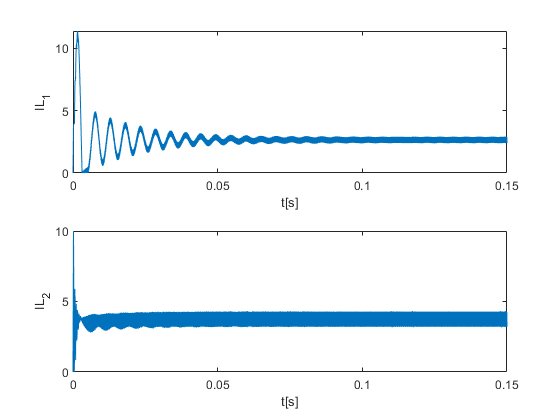

figure(5)
subplot(2,1,1)
plot(t,IL1)
xlabel('t[s]');
ylabel('IL_1');
subplot(2,1,2)
plot(t,IL2)
xlabel('t[s]');
ylabel('IL_2');

#### 4.2.3 Formas de onda das tensões nos capacitores para uma referência de tensão Vref

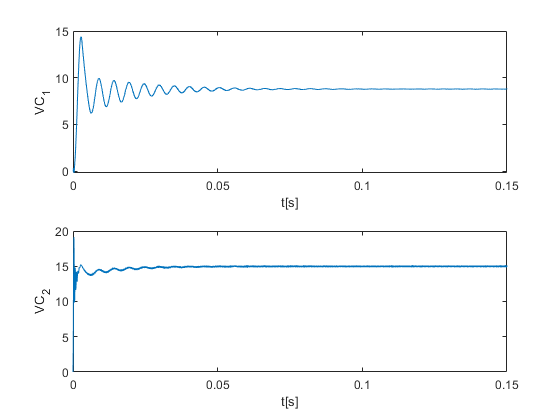

figure(6);
subplot(2,1,1)
plot(t,VC1);
xlabel('t[s]');
ylabel('VC_1');
subplot(2,1,2)
plot(t,VC2);
xlabel('t[s]');
ylabel('VC_2');

#### 4.2.4 Forma de onda da tensão de saída do conversor a um degrau de referência de tensão

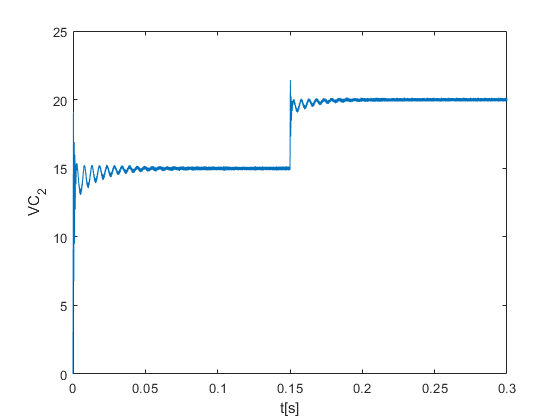

tempo_f = 0.30;
Delta_t = double((1/fch)/100);
t = 0:Delta_t:tempo_f;
DenteSerra = (sawtooth(2*pi*fch*t)*0.5)+0.5;
t_size = size(t);
t_size = t_size(1,2);
x = zeros(t_size,rank(A1));
u = ones(t_size,1)*Vin;

u_PID = zeros(t_size,1);
y_PID = zeros(t_size,1);
x_PID = zeros(t_size,3);

M1 = inv(eye(rank(A1))-((Delta_t/2)*A1))*(eye(rank(A1))+(Delta_t/2)*A1);
N1 = inv(eye(rank(A1))-((Delta_t/2)*A1))*((Delta_t/2)*B1);
M2 = inv(eye(rank(A2))-((Delta_t/2)*A2))*(eye(rank(A2))+(Delta_t/2)*A2);
N2 = inv(eye(rank(A2))-((Delta_t/2)*A2))*((Delta_t/2)*B2);

M_PID = inv(eye(3)-((Delta_t/2)*A_PID))*(eye(3)+(Delta_t/2)*A_PID);
N_PID = inv(eye(3)-((Delta_t/2)*A_PID))*((Delta_t/2)*B_PID);

for i = 1:t_size
    if i < 3
        x(i,:) = zeros(1,4);
        x_PID(i,:) = zeros(1,3);
    else
        if t(i) < 0.15
            Vo_ref = 15;
        else
            Vo_ref = 20;
        end
        u_PID(i) = Vo_ref-x(i-1,4);
        x_PID(i,:) = (M_PID*x_PID(i-1,:)'+N_PID*(u_PID(i)+u_PID(i-1)))';
        y_PID(i) = C_PID*x_PID(i,:)'+E_PID*u_PID(i);
        D = y_PID(i);
        if D < 0
            D = 0;
        end
        if D > 1
            D = 1;
        end
        if D < DenteSerra(i)
            M = M2;
            N = N2;
        else
            M = M1;
            N = N1;
        end
        x(i,:) =(M*x(i-1,:)'+N*(u(i)+u(i-1)))';
    end
end
IL1 = x(:,1);
IL2 = x(:,2);
VC1 = x(:,3);
VC2 = x(:,4);
figure(8);
plot(t,VC2);
xlabel('t[s]');
ylabel('VC_2');

#### 4.2.5 Forma de onda da tensão de saída do conversor a uma variação de carga

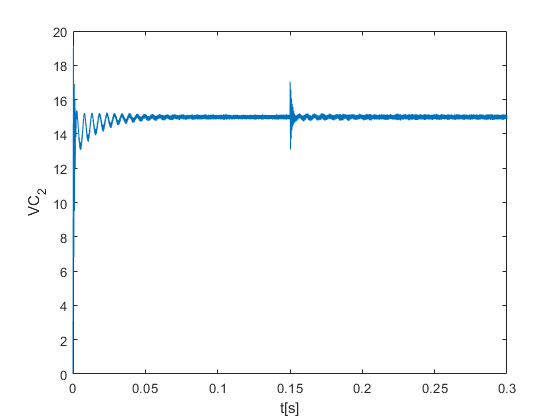

L1 = abs(double(subs(valorL1)));
L2 = abs(double(subs(valorL2)));
C1 = abs(double(subs(valorC1)));
C2 = abs(double(subs(valorC2)));

R  = 4;
A1_R1 = double(subs(A1_symb));
A2_R1 = double(subs(A2_symb));
B1_R1 = double(subs(B1_symb));
B2_R1 = double(subs(B2_symb));
M1_R1 = inv(eye(rank(A1_R1))-((Delta_t/2)*A1_R1))*(eye(rank(A1_R1))+(Delta_t/2)*A1_R1);
N1_R1 = inv(eye(rank(A1_R1))-((Delta_t/2)*A1_R1))*((Delta_t/2)*B1_R1);
M2_R1 = inv(eye(rank(A2_R1))-((Delta_t/2)*A2_R1))*(eye(rank(A2_R1))+(Delta_t/2)*A2_R1);
N2_R1 = inv(eye(rank(A2_R1))-((Delta_t/2)*A2_R1))*((Delta_t/2)*B2_R1);
R  = 8;
A1_R2 = double(subs(A1_symb));
A2_R2 = double(subs(A2_symb));
B1_R2 = double(subs(B1_symb));
B2_R2 = double(subs(B2_symb));
M1_R2 = inv(eye(rank(A1_R2))-((Delta_t/2)*A1_R2))*(eye(rank(A1_R2))+(Delta_t/2)*A1_R2);
N1_R2 = inv(eye(rank(A1_R2))-((Delta_t/2)*A1_R2))*((Delta_t/2)*B1_R2);
M2_R2 = inv(eye(rank(A2_R2))-((Delta_t/2)*A2_R2))*(eye(rank(A2_R2))+(Delta_t/2)*A2_R2);
N2_R2 = inv(eye(rank(A2_R2))-((Delta_t/2)*A2_R2))*((Delta_t/2)*B2_R2);

tempo_f = 0.30;
Vo_ref = 15;
Delta_t = double((1/fch)/100);
t = 0:Delta_t:tempo_f;
DenteSerra = (sawtooth(2*pi*fch*t)*0.5)+0.5;
t_size = size(t);
t_size = t_size(1,2);
x = zeros(t_size,rank(A1));
u = ones(t_size,1)*Vin;

u_PID = zeros(t_size,1);
y_PID = zeros(t_size,1);
x_PID = zeros(t_size,3);

M_PID = inv(eye(3)-((Delta_t/2)*A_PID))*(eye(3)+(Delta_t/2)*A_PID);
N_PID = inv(eye(3)-((Delta_t/2)*A_PID))*((Delta_t/2)*B_PID);

for i = 1:t_size
    if i < 3
        x(i,:) = zeros(1,4);
        x_PID(i,:) = zeros(1,3);
    else
        if t(i) < 0.15
            M1 = M1_R1;
            N1 = N1_R1;
            M2 = M2_R1;
            N2 = N2_R1;
        else
            M1 = M1_R2;
            N1 = N1_R2;
            M2 = M2_R2;
            N2 = N2_R2;
        end
        u_PID(i) = Vo_ref-x(i-1,4);
        x_PID(i,:) = (M_PID*x_PID(i-1,:)'+N_PID*(u_PID(i)+u_PID(i-1)))';
        y_PID(i) = C_PID*x_PID(i,:)'+E_PID*u_PID(i);
        D = y_PID(i);
        if D < 0
            D = 0;
        end
        if D > 1
            D = 1;
        end
        if D < DenteSerra(i)
            M = M2;
            N = N2;
        else
            M = M1;
            N = N1;
        end
        x(i,:) =(M*x(i-1,:)'+N*(u(i)+u(i-1)))';
    end
end
IL1 = x(:,1);
IL2 = x(:,2);
VC1 = x(:,3);
VC2 = x(:,4);
figure(9);
plot(t,VC2);
xlabel('t[s]');
ylabel('VC_2');

#### 4.2.6 Forma de onda da tensão de saída do conversor um afundamento na tensão de alimentação

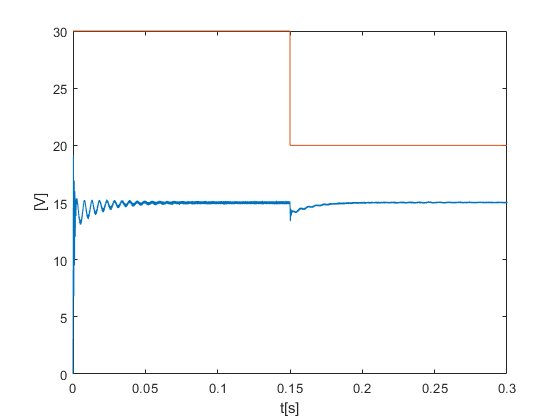

L1 = abs(double(subs(valorL1)));
L2 = abs(double(subs(valorL2)));
C1 = abs(double(subs(valorC1)));
C2 = abs(double(subs(valorC2)));
R  = abs(double(subs(valorR)));
A1 = double(subs(A1_symb));
A2 = double(subs(A2_symb));
B1 = double(subs(B1_symb));
B2 = double(subs(B2_symb));
tempo_f = 0.30;
Delta_t = double((1/fch)/100);
t = 0:Delta_t:tempo_f;
DenteSerra = (sawtooth(2*pi*fch*t)*0.5)+0.5;
t_size = size(t);
t_size = t_size(1,2);
x = zeros(t_size,rank(A1));
u = ones(t_size,1)*Vin;

u_PID = zeros(t_size,1);
y_PID = zeros(t_size,1);
x_PID = zeros(t_size,3);

M1 = inv(eye(rank(A1))-((Delta_t/2)*A1))*(eye(rank(A1))+(Delta_t/2)*A1);
N1 = inv(eye(rank(A1))-((Delta_t/2)*A1))*((Delta_t/2)*B1);
M2 = inv(eye(rank(A2))-((Delta_t/2)*A2))*(eye(rank(A2))+(Delta_t/2)*A2);
N2 = inv(eye(rank(A2))-((Delta_t/2)*A2))*((Delta_t/2)*B2);

M_PID = inv(eye(3)-((Delta_t/2)*A_PID))*(eye(3)+(Delta_t/2)*A_PID);
N_PID = inv(eye(3)-((Delta_t/2)*A_PID))*((Delta_t/2)*B_PID);

for i = 1:t_size
    if i < 3
        x(i,:) = zeros(1,4);
        x_PID(i,:) = zeros(1,3);
    else
        if t(i) < 0.15
            u(i) = 30;
        else
            u(i) = 20;
        end
        u_PID(i) = Vo_ref-x(i-1,4);
        x_PID(i,:) = (M_PID*x_PID(i-1,:)'+N_PID*(u_PID(i)+u_PID(i-1)))';
        y_PID(i) = C_PID*x_PID(i,:)'+E_PID*u_PID(i);
        D = y_PID(i);
        if D < 0
            D = 0;
        end
        if D > 1
            D = 1;
        end
        if D < DenteSerra(i)
            M = M2;
            N = N2;
        else
            M = M1;
            N = N1;
        end
        x(i,:) =(M*x(i-1,:)'+N*(u(i)+u(i-1)))';
    end
end
IL1 = x(:,1);
IL2 = x(:,2);
VC1 = x(:,3);
VC2 = x(:,4);
figure(10);
plot(t,VC2,t,u);
xlabel('t[s]');
ylabel('[V]');